# Machine Learning: Programming Exercise 2 

## Logistic Regression

In this exercise, you will implement logistic regression and apply it to two different datasets.

### Files needed for this exercise

- `ex2.mlx` - MATLAB Live Script that steps you through the exercise

- ex2data1.txt - Training set for the first half of the exercise

- ex2data2.txt - Training set for the second half of the exercise

- `submit.m` - Submission script that sends your solutions to our servers

- `mapFeature.m` - Function to generate polynomial features

- `plotDecisionBoundary.m` - Function to plot classifier's decision boundary

- *`plotData.m` - Function to plot 2D classification data

- *`sigmoid.m` - Sigmoid function

- *`costFunction.m` - Logistic regression cost function

- *`predict.m` - Logistic regression prediction function

- `*costFunctionReg.m` - Regularized logistic regression cost function

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex2' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir


.                       costFunctionReg.m       ex2data1.txt            mapFeature.m            predict.m               token.mat               
..                      ex2.mlx                 ex2data2.txt            plotData.m              sigmoid.m               
costFunction.m          ex2_companion.mlx       lib                     plotDecisionBoundary.m  submit.m                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Logistic Regression

In this part of the exercise, you will build a logistic regression model to predict whether a student gets admitted into a university. Suppose that you are the administrator of a university department and you want to determine each applicant's chance of admission based on their results on two exams. You have historical data from previous applicants that you can use as a training set for logistic regression. For each training example, you have the applicant's scores on two exams and the admissions decision.

    Your task is to build a classification model that estimates an applicant's probability of admission based the scores from those two exams. `ex2.mlx` will guide you through the exercise. To begin, run the code below to load the data into MATLAB.

% Load Data
% The first two columns contain the exam scores and the third column contains the label.
data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

### 1.1 Visualizing the data

Before starting to implement any learning algorithm, it is always good to visualize the data if possible. The code below will load the data and display it on a 2-dimensional plot by calling the function `plotData`. You will now complete the code in `plotData` so that it displays a figure like Figure 1, where the axes are the two exam scores, and the positive and negative examples are shown with different markers.

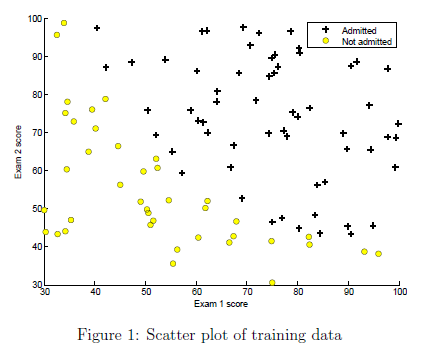

To help you get more familiar with plotting, we have left `plotData.m` empty so you can try to implement it yourself. However, this is an optional (ungraded) exercise. We also provide our implementation below so you can copy it or refer to it. If you choose to copy our example, make sure you learn what each of its commands is doing by consulting the MATLAB documentation.

Once you have added your own or the above code to `plotData.m`, run the code in this section to call the `plotData` function.

% Plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples.
plotData(X, y);

neg =      1
     2
     3
     6
    11
    12
    15
    18
    21
    23


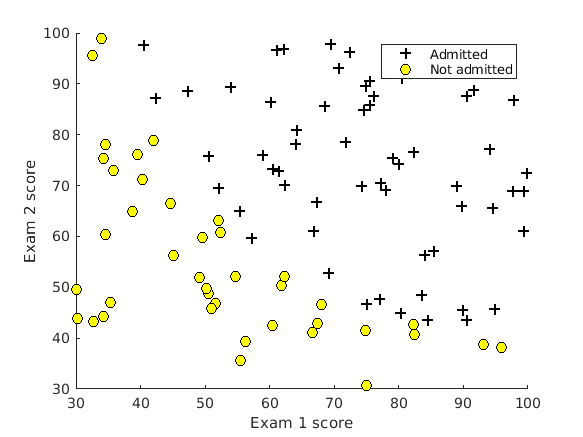

 
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')

### 1.2 Implementation

#### 1.2.1 Warmup exercise: sigmoid function

Before you start with the actual cost function, recall that the logistic regression hypothesis is defined as:


$$ h_{\theta}(x) = g(\theta^Tx),$$


where function $g$ is the sigmoid function. The sigmoid function is defined as:


$$g(z) = \frac{1}{1+e^{-z}}$$


    Your first step is to implement this function in `sigmoid.m` so it can be called by the rest of your program. When you are finished, try testing a few values by calling `sigmoid(x)` in the code section below. For large positive values of `x`, the sigmoid should be close to 1, while for large negative values, the sigmoid should be close to 0. Evaluating `sigmoid(0)` should give you exactly 0.5. **Your code should also work with vectors and matrices**. For a matrix, your function should perform the sigmoid function on every element.

% Provide input values to the sigmoid function below and run to check your implementation
sigmoid(0)

ans = 0.5000

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.2.2 Cost function and gradient

Now you will implement the cost function and gradient for logistic regression. Complete the code in `costFunction.m` to return the cost and gradient. Recall that the cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


and the gradient of the cost is a vector of the same length as $\theta$ where the $j$th element (for $j = 0,\; 1,\ldots, n)$ is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}$$


Note that while this gradient looks identical to the linear regression gradient, the formula is actually different because linear and logistic regression have different definitions of $h_{\theta}(x)$. Once you are done, run the code sections below to set up your data and call your `costFunction` using the initial parameters of $\theta$. You should see that the cost is about 0.693 and gradients of about -0.1000,  -12.0092, and -11.2628

%  Setup the data matrix appropriately
[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];

% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


disp('Gradient at initial theta (zeros):'); disp(grad);

Gradient at initial theta (zeros):
   -0.1000
  -12.0092
  -11.2628



#### 1.2.3 Learning parameters using `fminunc`

In the previous assignment, you found the optimal parameters of a linear regression model by implementing gradent descent. You wrote a cost function and calculated its gradient, then took a gradient descent step accordingly. This time, instead of taking gradient descent steps, you will use a MATLAB built-in function called `fminunc`. 

    MATLAB's `fminunc` is an optimization solver that finds the minimum of an unconstrained* function. For logistic regression, you want to optimize the cost function $J(\theta)$ with parameters. Concretely, you are going to use `fminunc` to find the best parameters $\theta$ for the logistic regression cost function, given a fixed dataset (of $X$ and $y$ values). You will pass to `fminunc` the following inputs:

- The initial values of the parameters we are trying to optimize.

- A function that, when given the training set and a particular $\theta$ computes the logistic regression cost and gradient with respect to $\theta$ for the dataset $(X, y)$

**Constraints in optimization often refer to constraints on the parameters, for example, constraints that bound the possible values *$\theta$* can take (e.g. *$\theta<1$*). Logistic regression does not have such constraints since *$\theta$* is allowed to take any real value.*

We already have code written below to call `fminunc` with the correct arguments:

- We first define the options to be used with `fminunc`. Specically, we set the `GradObj` option to `on`, which tells `fminunc` that our function returns both the cost and the gradient. This allows `fminunc` to use the gradient when minimizing the function. 

- Furthermore, we set the `MaxIter` option to 400, so that `fminunc` will run for at most 400 steps before it terminates. 

- To specify the actual function we are minimizing, we use a 'short-hand' for specifying functions with: `@(t)(costFunction(t,X,y))`. This creates a function, with argument `t`, which calls your `costFunction`. This allows us to wrap the `costFunction` for use with `fminunc`.

- If you have completed the `costFunction` correctly, `fminunc` will converge on the right optimization parameters and return the final values of the cost and $\theta$. Notice that by using `fminunc`, you did not have to write any loops yourself, or set a learning rate like you did for gradient descent. This is all done by `fminunc`: you only needed to provide a function calculating the cost and the gradient.

- Once `fminunc` completes, the remaining code will call your `costFunction` function using the optimal parameters of $\theta$. You should see that the cost is about 0.203. This final $\theta$ value will then be used to plot the decision boundary on the training data, resulting in a figure similar to Figure 2. We also encourage you to look at the code in `plotDecisionBoundary.m` to see how to plot such a boundary using the $\theta$ values.

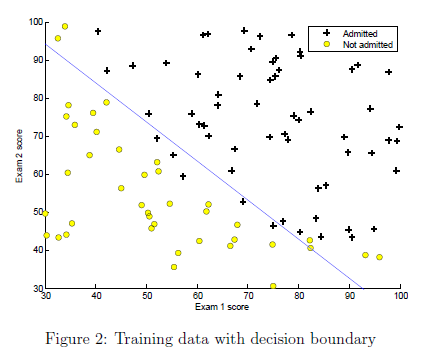

Run the code below and verify the results.

%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203498


disp('theta:');disp(theta);

theta:
  -25.1613
    0.2062
    0.2015




% Plot Boundary
plotDecisionBoundary(theta, X, y);

neg =      1
     2
     3
     6
    11
    12
    15
    18
    21
    23


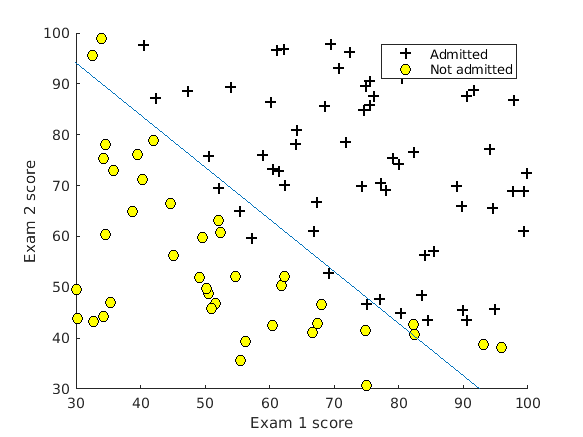

% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

#### 1.2.4 Evaluating logistic regression

After learning the parameters, you can use the model to predict whether a particular student will be admitted. For a student with an Exam 1 score of 45 and an Exam 2 score of 85, you should expect to see an admission probability of 0.776. Another way to evaluate the quality of the parameters we have found is to see how well the learned model predicts on our training set. In this part, your task is to complete the code in `predict.m`. The predict function will produce '1' or '0' predictions given a dataset and a learned parameter vector $\theta$.

    After you have completed the code in `predict.m`, the code below will proceed to report the training accuracy of your classifier by computing the percentage of examples it got correct. 

%  Predict probability for a student with score 45 on exam 1  and score 85 on exam 2 
prob = sigmoid([1 45 85] .* theta);
fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict an admission probability of 0.000000

For a student with scores 45 and 85, we predict an admission probability of 0.551376

For a student with scores 45 and 85, we predict an admission probability of 0.550198

For a student with scores 45 and 85, we predict an admission probability of 0.000000

For a student with scores 45 and 85, we predict an admission probability of 0.999907

For a student with scores 45 and 85, we predict an admission probability of 0.999885

For a student with scores 45 and 85, we predict an admission probability of 0.000000

For a student with scores 45 and 85, we predict an admission probability of 1.000000

For a student with scores 45 and 85, we predict an admission probability of 1.000000



% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 89.000000


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Regularized logistic regression

In this part of the exercise, you will implement regularized logistic regression to predict whether microchips from a fabrication plant passes quality assurance (QA). During QA, each microchip goes through various tests to ensure it is functioning correctly. Suppose you are the product manager of the factory and you have the test results for some microchips on two different tests. From these two tests, you would like to determine whether the microchips should be accepted or rejected. To help you make the decision, you have a dataset of test results on past microchips, from which you can build a logistic regression model.

### 2.1 Visualizing the data

Similar to the previous parts of this exercise, `plotData` is used in the code below to generate a figure like Figure 3, where the axes are the two test scores, and the positive ($y=1,$  accepted) and negative ($y=0,$ rejected) examples are shown with different markers. 

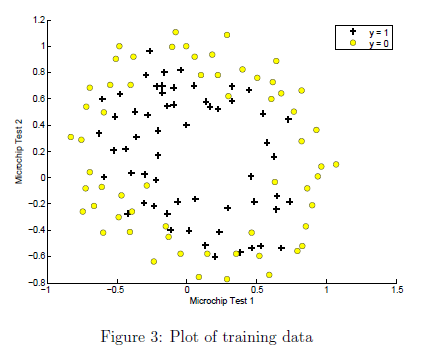

Run the code below and confirm you plot matches Figure 3.

%  The first two columns contains the X values and the third column
%  contains the label (y).
data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);

neg =     59
    60
    61
    62
    63
    64
    65
    66
    67
    68


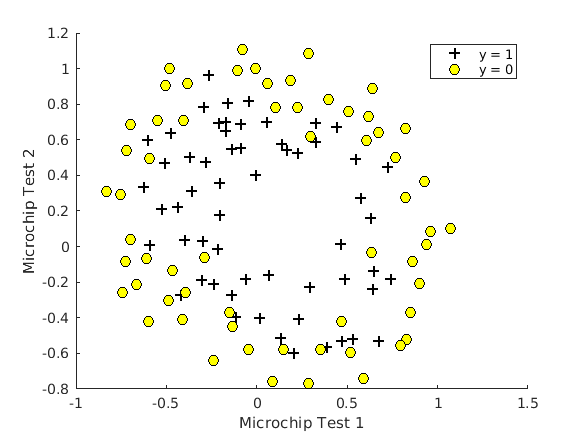

% Put some labels 
hold on;
% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

        Figure 3 shows that our dataset cannot be separated into positive and negative examples by a straight-line through the plot. Therefore, a straightforward application of logistic regression will not perform well on this dataset since logistic regression will only be able to find a linear decision boundary.

### 2.2 Feature mapping

One way to fit the data better is to create more features from each data point. In the provided function `mapFeature.m`, we will map the features into all polynomial terms of $x_1$ and $x_2$ up to the sixth power.


$$\text{mapFeature}\left(x\right)=\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\vdots \text{ }\\
x_1 x_2^5 \\
x_2^6 
\end{array}\right\rbrack$$


    As a result of this mapping, our vector of two features (the scores on two QA tests) has been transformed into a 28-dimensional vector. A logistic regression classifier trained on this higher-dimension feature vector will have a more complex decision boundary and will appear nonlinear when drawn in our 2-dimensional plot. 

    Run the code below to map the features.

% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, so the intercept term is handled
X = mapFeature(X(:,1), X(:,2));

    While the feature mapping allows us to build a more expressive classifier, it also more susceptible to overfitting. In the next parts of the exercise, you will implement regularized logistic regression to fit the data and also see for yourself how regularization can help combat the overfitting problem.

### 2.3 Cost function and gradient

Now you will implement code to compute the cost function and gradient for regularized logistic regression. Complete the code in `costFunctionReg.m` to return the cost and gradient. Recall that the regularized cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[
-y^{(i)} \log(h_{\theta}(x^{(i)}))-(1-y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2},$$


Note that you should not regularize the parameter $\theta_0$. In MATLAB, recall that indexing starts from 1, hence, you should not be regularizing the `theta(1)` parameter (which corresponds to $\theta_0$) in the code. The gradient of the cost function is a vector where the $j\mathrm{th}$ element is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


Once you are done, run the code below to call your `costFunctionReg` function using the initial value of $\theta$ (initialized to all zeros). You should see that the cost is about 0.693.

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);

hx =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


grad =     0.0085
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0085
    0.0188
    0.0001
    0.0503
    0.0115
    0.0377
    0.0184
    0.0073
    0.0082
    0.0235


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.3.1 Learning parameters using `fminunc`

Similar to the previous parts, the next step is to use `fminunc` to learn the optimal parameters. If you have completed the cost and gradient for regularized logistic regression (`costFunctionReg.m`) correctly, you should be able to run the code in the following sections to learn the parameters using `fminunc` for multiple values of $\lambda$.

### 2.4 Plotting the decision boundary

To help you visualize the model learned by this classifier, we have provided the function `plotDecisionBoundary.m` which plots the (nonlinear) decision boundary that separates the positive and negative examples. In `plotDecisionBoundary.m`, we plot the nonlinear decision boundary by computing the classifier's predictions on an evenly spaced grid and then drew a contour plot of where the predictions change from $y = 0$ to $y = 1$. After learning the parameters, the code in the next section will plot a decision boundary similar to Figure 4.

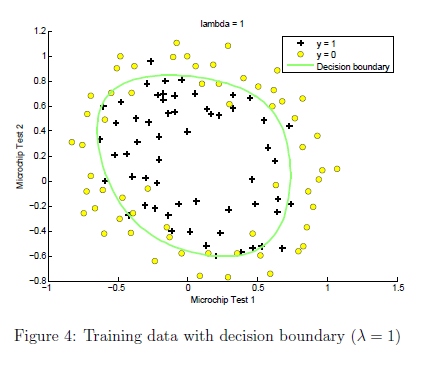

### 2.5 Optional (ungraded) exercises

In this part of the exercise, you will get to try out different regularization parameters for the dataset to understand how regularization prevents overfitting. Notice the changes in the decision boundary as you vary $\lambda$. With a small $\lambda$, you should find that the classifier gets almost every training example correct, but draws a very complicated boundary, thus overfitting the data (Figure 5). 

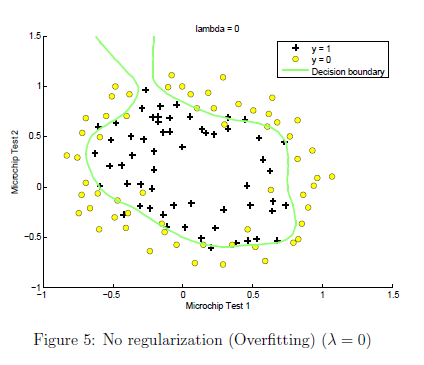

    This is not a good decision boundary: for example, it predicts that a point at $x = (0.25, 1.5)$ is accepted $(y = 1)$, which seems to be an incorrect decision given the training set. With a larger $\lambda$, you should see a plot that shows an simpler decision boundary which still separates the positives and negatives fairly well. However, if $\lambda$ is set to too high a value, you will not get a good fit and the decision boundary will not follow the data so well, thus underfitting the data (Figure 6).

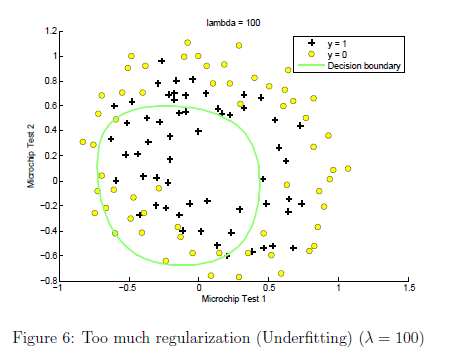

Use the control below to try the following values of $\lambda$: 0, 1, 10, 100. 

- How does the decision boundary change when you vary $\lambda$? 

- How does the training set accuracy vary?

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 1;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);

hx =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


grad =     0.0085
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0085
    0.0188
    0.0001
    0.0503
    0.0115
    0.0377
    0.0184
    0.0073
    0.0082
    0.0235


hx =     0.4860
    0.4879
    0.4879
    0.4943
    0.4941
    0.4966
    0.4978
    0.4978
    0.4964
    0.4949


grad =    -0.0071
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0071
    0.0144
   -0.0064
    0.0447
    0.0112
    0.0302
    0.0152
    0.0062
    0.0074
    0.0180


hx =     0.4771
    0.4947
    0.4951
    0.5450
    0.5378
    0.5483
    0.5566
    0.5488
    0.5331
    0.5148


grad =    -0.0511
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0511
   -0.0175
   -0.0307
    0.0168
    0.0074
   -0.0002
   -0.0061
    0.0016
    0.0017
   -0.0065


hx =     0.5355
    0.5616
    0.5596
    0.6281
    0.6090
    0.6163
    0.6295
    0.6135
    0.5905
    0.5590


grad =    -0.0341
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0341
   -0.0304
   -0.0292
    0.0092
    0.0048
   -0.0033
   -0.0140
    0.0010
   -0.0008
   -0.0108


hx =     0.6186
    0.6468
    0.6387
    0.7091
    0.6731
    0.6715
    0.6918
    0.6680
    0.6452
    0.6024


grad =    -0.0073
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0073
   -0.0330
   -0.0202
    0.0047
    0.0032
   -0.0010
   -0.0164
    0.0011
   -0.0017
   -0.0102


hx =     0.6707
    0.6947
    0.6807
    0.7410
    0.6909
    0.6804
    0.7076
    0.6797
    0.6633
    0.6157


grad =     0.0044
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0044
   -0.0263
   -0.0119
    0.0020
    0.0033
    0.0012
   -0.0140
    0.0014
   -0.0011
   -0.0078


hx =     0.7115
    0.7278
    0.7071
    0.7502
    0.6827
    0.6606
    0.6971
    0.6656
    0.6610
    0.6111


grad =     0.0083
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0083
   -0.0125
   -0.0028
   -0.0002
    0.0043
    0.0034
   -0.0082
    0.0017
    0.0007
   -0.0042


hx =     0.7215
    0.7324
    0.7080
    0.7376
    0.6585
    0.6285
    0.6712
    0.6384
    0.6439
    0.5950


grad =     0.0048
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0048
   -0.0010
    0.0020
   -0.0004
    0.0053
    0.0045
   -0.0028
    0.0018
    0.0022
   -0.0014


hx =     0.7156
    0.7252
    0.7002
    0.7244
    0.6423
    0.6099
    0.6541
    0.6215
    0.6308
    0.5834


grad = 	1.0e+-3 *

    0.6226
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0006
    0.0035
    0.0027
    0.0002
    0.0054
    0.0045
   -0.0004
    0.0017
    0.0027
   -0.0004


hx =     0.7084
    0.7187
    0.6946
    0.7175
    0.6354
    0.6025
    0.6467
    0.6142
    0.6242
    0.5775


grad =    -0.0022
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0022
    0.0045
    0.0021
    0.0005
    0.0048
    0.0040
    0.0004
    0.0014
    0.0025
   -0.0001


hx =     0.6980
    0.7115
    0.6900
    0.7128
    0.6320
    0.5988
    0.6425
    0.6094
    0.6190
    0.5720


grad =    -0.0052
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0052
    0.0042
    0.0007
    0.0008
    0.0029
    0.0028
    0.0010
    0.0008
    0.0016
   -0.0000


hx =     0.6933
    0.7111
    0.6927
    0.7174
    0.6381
    0.6046
    0.6478
    0.6134
    0.6211
    0.5724


grad =    -0.0052
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0052
    0.0024
   -0.0004
    0.0006
    0.0005
    0.0016
    0.0008
    0.0001
    0.0004
   -0.0001


hx =     0.6962
    0.7167
    0.6999
    0.7267
    0.6481
    0.6147
    0.6579
    0.6223
    0.6280
    0.5773


grad =    -0.0026
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0026
    0.0005
   -0.0005
    0.0003
   -0.0010
    0.0011
    0.0003
   -0.0003
   -0.0005
   -0.0001


hx =     0.6996
    0.7204
    0.7037
    0.7313
    0.6527
    0.6197
    0.6631
    0.6272
    0.6320
    0.5804


grad = 	1.0e+-3 *

   -0.8414
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0008
   -0.0000
   -0.0002
    0.0001
   -0.0012
    0.0011
    0.0000
   -0.0003
   -0.0006
   -0.0001


hx =     0.7014
    0.7220
    0.7051
    0.7331
    0.6544
    0.6220
    0.6657
    0.6297
    0.6340
    0.5818


grad = 	1.0e+-3 *

    0.1583
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0002
   -0.0001
    0.0001
    0.0002
   -0.0010
    0.0011
   -0.0001
   -0.0003
   -0.0005
   -0.0001


hx =     0.7032
    0.7234
    0.7059
    0.7346
    0.6557
    0.6250
    0.6693
    0.6333
    0.6365
    0.5833


grad =     0.0014
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0014
   -0.0002
    0.0003
    0.0003
   -0.0006
    0.0010
   -0.0001
   -0.0001
   -0.0004
    0.0000


hx =     0.7031
    0.7228
    0.7047
    0.7342
    0.6551
    0.6268
    0.6719
    0.6361
    0.6378
    0.5833


grad =     0.0019
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0019
   -0.0002
    0.0005
    0.0004
   -0.0001
    0.0007
   -0.0000
   -0.0000
   -0.0002
    0.0001


hx =     0.7009
    0.7204
    0.7020
    0.7320
    0.6528
    0.6263
    0.6719
    0.6363
    0.6370
    0.5818


grad =     0.0013
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.0013
   -0.0001
    0.0003
    0.0004
    0.0002
    0.0002
    0.0001
   -0.0000
   -0.0001
    0.0001


hx =     0.6992
    0.7186
    0.7002
    0.7303
    0.6510
    0.6250
    0.6707
    0.6352
    0.6358
    0.5805


grad =     0.3545
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.3545
   -0.0420
    0.1216
    0.2987
    0.2350
   -0.0681
    0.1510
   -0.0382
   -0.1171
    0.1159


hx =     0.6986
    0.7181
    0.6998
    0.7297
    0.6504
    0.6243
    0.6700
    0.6345
    0.6352
    0.5801


grad =    -0.5946
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.0595
   -0.0475
    0.0451
    0.2085
    0.1949
   -0.1248
    0.1392
   -0.0564
   -0.1286
    0.0974


hx =     0.6983
    0.7179
    0.6995
    0.7294
    0.6500
    0.6237
    0.6695
    0.6340
    0.6350
    0.5800


grad =    -0.3459
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.3459
   -0.0620
   -0.0046
    0.0993
    0.1497
   -0.1382
    0.1066
   -0.0691
   -0.1315
    0.0842


hx =     0.6983
    0.7178
    0.6995
    0.7291
    0.6497
    0.6233
    0.6691
    0.6337
    0.6351
    0.5802


grad =    -0.5203
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.5203
   -0.0786
   -0.0417
   -0.0459
    0.0977
   -0.1053
    0.0485
   -0.0753
   -0.1147
    0.0770


hx =     0.6986
    0.7180
    0.6996
    0.7292
    0.6496
    0.6233
    0.6693
    0.6339
    0.6355
    0.5809


grad =    -0.3957
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.3957
   -0.0746
   -0.0469
   -0.1268
    0.0692
   -0.0263
    0.0010
   -0.0676
   -0.0768
    0.0800


hx =     0.6989
    0.7183
    0.6998
    0.7294
    0.6498
    0.6236
    0.6696
    0.6343
    0.6361
    0.5815


grad =    -0.1218
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.1218
   -0.0479
   -0.0395
   -0.1103
    0.0655
    0.0438
   -0.0096
   -0.0544
   -0.0407
    0.0814


hx =     0.6990
    0.7184
    0.6999
    0.7295
    0.6500
    0.6238
    0.6698
    0.6345
    0.6363
    0.5818


grad =     0.6481
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.6481
   -0.1779
   -0.4220
   -0.6120
    0.6539
    0.7256
    0.0108
   -0.4531
   -0.2018
    0.7276


hx =     0.6990
    0.7183
    0.6999
    0.7296
    0.6501
    0.6240
    0.6700
    0.6346
    0.6364
    0.5819


grad =     0.1789
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.1789
    0.0150
   -0.0561
   -0.0087
    0.0578
    0.0770
    0.0168
   -0.0374
   -0.0045
    0.0519


hx =     0.6988
    0.7182
    0.6998
    0.7297
    0.6502
    0.6241
    0.6700
    0.6346
    0.6364
    0.5819


grad =     0.2089
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.2089
    0.0470
   -0.0769
    0.0360
    0.0381
    0.0562
    0.0308
   -0.0279
    0.0087
    0.0168


hx =     0.6987
    0.7181
    0.6997
    0.7297
    0.6503
    0.6241
    0.6699
    0.6344
    0.6362
    0.5817


grad =     0.1296
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.1296
    0.0569
   -0.0838
    0.0456
    0.0132
    0.0175
    0.0309
   -0.0177
    0.0136
   -0.0157


hx =     0.6986
    0.7180
    0.6996
    0.7297
    0.6503
    0.6241
    0.6698
    0.6342
    0.6359
    0.5815


grad =     0.2233
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.2233
    0.3995
   -0.6390
    0.2441
   -0.0194
   -0.1100
    0.1751
   -0.0900
    0.0979
   -0.2479


hx =     0.6986
    0.7181
    0.6997
    0.7297
    0.6504
    0.6241
    0.6697
    0.6341
    0.6358
    0.5813


grad =    -0.2501
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.2501
    0.1808
   -0.3388
    0.0521
   -0.0437
   -0.1618
    0.0461
   -0.0310
    0.0451
   -0.1560


hx =     0.6987
    0.7181
    0.6997
    0.7297
    0.6504
    0.6241
    0.6697
    0.6341
    0.6358
    0.5813


grad =    -0.2283
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.2283
    0.0535
   -0.1173
   -0.0012
   -0.0249
   -0.1024
   -0.0154
    0.0051
    0.0175
   -0.0471


hx =     0.6987
    0.7182
    0.6998
    0.7297
    0.6504
    0.6241
    0.6697
    0.6341
    0.6358
    0.5813


grad =    -0.8266
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.8266
    0.1046
   -0.1090
    0.1917
   -0.1143
   -0.4199
   -0.2881
    0.2348
    0.1019
    0.1228


hx =     0.6987
    0.7182
    0.6998
    0.7298
    0.6505
    0.6241
    0.6698
    0.6341
    0.6358
    0.5813


grad =     0.1065
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.1065
    0.0402
    0.2322
    0.4490
   -0.0855
   -0.1069
   -0.2551
    0.2997
    0.0978
    0.3183


hx =     0.6987
    0.7182
    0.6998
    0.7298
    0.6505
    0.6241
    0.6698
    0.6341
    0.6358
    0.5813


grad =     0.7849
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.7849
    0.0389
    0.3998
    0.6604
   -0.0882
    0.1246
   -0.1838
    0.3247
    0.0977
    0.4056


hx =     0.6987
    0.7182
    0.6998
    0.7298
    0.6505
    0.6241
    0.6698
    0.6341
    0.6358
    0.5813


grad =     0.1351
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.1351
    0.0047
    0.0489
    0.0807
   -0.0100
    0.0351
   -0.0067
    0.0307
    0.0086
    0.0425


hx =     0.6987
    0.7182
    0.6998
    0.7298
    0.6505
    0.6241
    0.6698
    0.6341
    0.6358
    0.5813


grad =     0.1354
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.1354
    0.0039
    0.0403
    0.0692
   -0.0096
    0.0426
    0.0053
    0.0217
    0.0055
    0.0314


hx =     0.6987
    0.7182
    0.6998
    0.7298
    0.6505
    0.6241
    0.6698
    0.6341
    0.6358
    0.5813


grad =     0.6863
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.6863
    0.0067
    0.1725
    0.3169
   -0.0599
    0.2619
    0.0939
    0.0945
    0.0204
    0.1152


hx =     0.6987
    0.7182
    0.6998
    0.7298
    0.6505
    0.6241
    0.6698
    0.6341
    0.6358
    0.5813


grad =     0.1224
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =     0.1224
   -0.0183
    0.0222
    0.0492
   -0.0233
    0.0770
    0.0640
    0.0363
    0.0084
    0.0015


hx =     0.6987
    0.7182
    0.6998
    0.7298
    0.6505
    0.6241
    0.6698
    0.6341
    0.6358
    0.5813


grad =    -0.1414
         0
         0
         0
         0
         0
         0
         0
         0
         0


grad =    -0.1414
   -0.2389
   -0.0575
   -0.0977
   -0.0973
    0.1850
    0.4231
    0.2977
    0.0931
   -0.1725



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


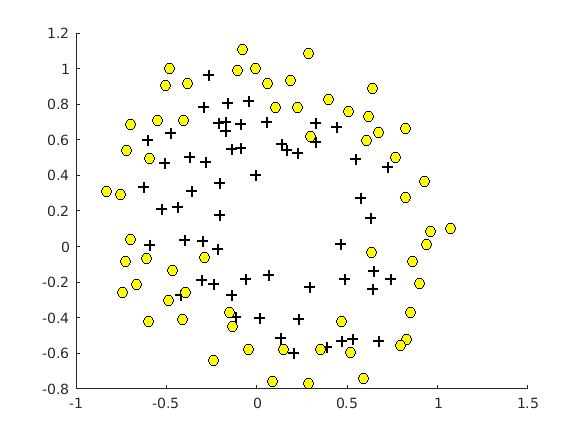

neg =     59
    60
    61
    62
    63
    64
    65
    66
    67
    68


Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 28-by-28.

Error in plotDecisionBoundary (line 37)
            z(i,j) = mapFeature(u(i), v(j)).*theta;

% Plot Boundary
plotDecisionBoundary(theta, X, y);

hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

*You do not need to submit any solutions for these optional (ungraded) exercises.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the `submit` function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

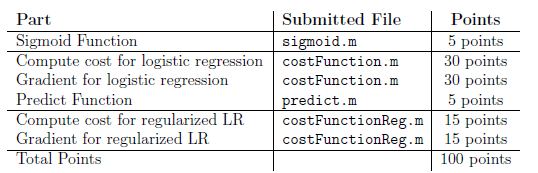

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.